set(0,'DefaultAxesFontSize',24,'DefaultAxesFontName','Times New Roman');
set(0,'DefaultTextFontSize',24,'DefaultTextFontName','Times New Roman'); 

data = importdata("lab325.xlsx");


U_R100 = data.data(23:44, 2);
Nu_R100 = data.data(23:44, 1);

[umax_R100, ind_U_R100] = max(U_R100);

U_new_R100 = U_R100/(U_R100(ind_U_R100));
Nu_new_R100 = Nu_R100/(Nu_R100(ind_U_R100));

U_R0 = data.data(23:41, 5);
Nu_R0 = data.data(23:41, 4);

[umax_R0, ind_U_R0] = max(U_R0);

U_new_R0 = U_R0/(U_R0(ind_U_R0));
Nu_new_R0 = Nu_R0/(Nu_R0(ind_U_R0));

plf_R100 = polyfit(Nu_new_R100, U_new_R100,10);
plf_R100_new = plf_R100;
plf_R100_new(end) = plf_R100_new(end) - 0.707;
rts_R100 = roots(plf_R100_new)';
delta_R100 = rts_R100(5) - rts_R100(6);
Q_R100 = (delta_R100)^-1

Q_R100 = 7.3327

sigma_Q_R100 = 0.283 * Q_R100

sigma_Q_R100 = 2.0752

plf_R0 = polyfit(Nu_new_R0, U_new_R0, 8);
plf_R0_new = plf_R0;
plf_R0_new(end) = plf_R0_new(end) - 0.707;
rts_R0 = roots(plf_R0_new)';
delta_R0 = rts_R0(4) - rts_R0(5);
Q_R0 = (delta_R0)^-1

Q_R0 = 25.4563

sigma_Q_R0 = 0.283 * Q_R0

sigma_Q_R0 = 7.2041

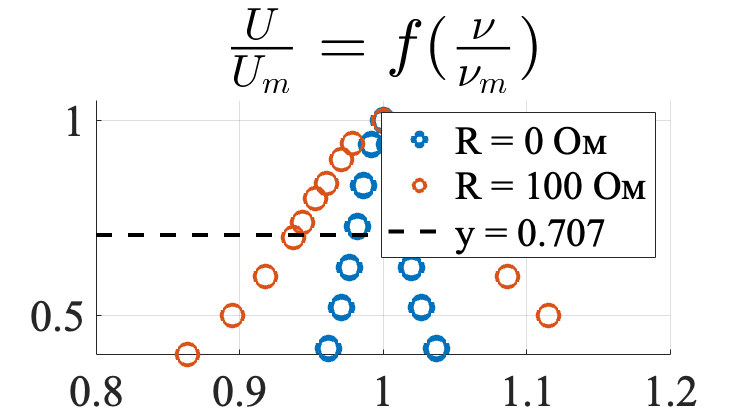



sz = 120;
fig1 = figure(Position=[0 0 1280 720]);
scatter(Nu_new_R0, U_new_R0, sz, LineWidth=3);
ylim([0.4 1.05])
xlim([0.8 1.2])
grid on
title('$\frac{U}{U_m} = f(\frac{\nu}{\nu_m}$)', 'Interpreter','latex', FontSize=32);
hold on
scatter(Nu_new_R100, U_new_R100, sz,LineWidth=2);
hold on
plot([0.5, 1.5], [0.707, 0.707], LineStyle="--", LineWidth=2, Color='black')
legend('R = 0 Ом', 'R = 100 Ом', 'y = 0.707');
saveas(fig1, 'plot.png');

C = 0.0000001

C = 1.0000e-07


Q0_teor = (sqrt(99.477*10^-3))/(30.814 * sqrt(C))

Q0_teor = 32.3678

Q100_teor = (sqrt(99.477*10^-3))/((100 + 30.814) * sqrt(C))

Q100_teor = 7.6244


theta1_up = (log((8.1 - 4.4)/(8.1 - 7.5)))/(14);
Q0_up = pi/theta1_up

Q0_up = 24.1773

dQ0_up = Q0_teor - Q0_up

dQ0_up = 8.1905

theta1_down = (log((4.2)/(1.6)))/(9);
Q0_down = pi/theta1_down

Q0_down = 29.2974

dQ0_down = Q0_teor - Q0_down

dQ0_down = 3.0704


theta2_up = (log((6.6 - 4.2)/(6.6 - 5.2)))/(1);
Q100_up = pi/theta2_up

Q100_up = 5.8286

dQ100_up = Q100_teor - Q100_up 

dQ100_up = 1.7958

theta2_down = (log((4)/(1.6)))/(2);
Q100_down = pi/theta2_down

Q100_down = 6.8572

dQ100_down = Q100_teor - Q100_down

dQ100_down = 0.7672